# Simulation Dynamics

This section presents the simulation dynamics of the model.

We begin by computing the baseline transition path of the economy under Business-As-Usual assumptions.

We then introduce an alternative carbon-policy scenario and solve for the corresponding transition to a net-zero economy.

Finally, we compare the two deterministic trajectories to assess the macroeconomic and climate implications of stronger mitigation efforts.

## I. Initialization of the path of the model

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.1).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Found 20 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the static model... 
11 block(s) found: 
  10 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Computing dynamic model derivatives (order 2). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
4 block(s) found: 
  3 recursive block(s) and 1 s

Residuals of the static equations:
Equation number  1: productivity trend        :       0.000000
Equation number  2: gZ                        :       0.000000
Equation number  3: population trend          :       0.000000
Equation number  4: emissions trend           :       0.000000
Equation number  5: cost of abatement - level :       0.000000
Equation number  6: efficiency trend          :       0.000000
Equation number  7: shocks                    :       0.000000
Equation number  8: Interest rate             :       0.000000
Equation number  9: Wage                      :       0.000000
Equation number 10: technology                :       0.000000
Equation number 11: MpH                       :       0.000000
Equation number 12: Optimal abatement         :       0.000000
Equation number 13: Emissions                 :       0.000000
Equation number 14: Ressources Constraint     :       0.000000
Equation number 15: Carbon stock              :       0.000000
Equation number 16: 

Error using print_info (line 33)
The steadystate file did not compute the steady state

Error in steady (line 143)
    print_info(info,options_.noprint, options_);

Error in model_file.driver (li


% solve the path for business as usual
[y_guess,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
[y_bau] 				= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);

## II. Scenario: transition with alternative carbon policy

### A. Solving the transition to net zero economy

We now consider a transition scenario in which the implementation of the carbon tax is modified. This is captured by updating the terminal state of the model with a new value of the policy parameter `varphi`. The routine `update_terminal_state` adjusts the long run conditions of the economy (for example, the terminal carbon stock and productivity) consistently with this new policy.

In the business-as-usual scenario, it is assumed that carbon tax path does not materializes: phi*tau with phi=0. But the tax path consistent with Paris-Agreement actually exists:

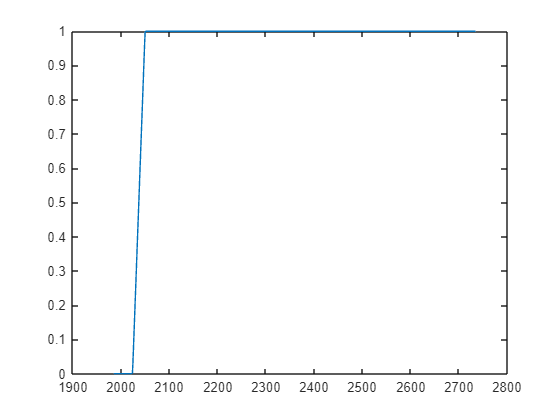

figure;
plotds('e_tau',exo_init_ts)

where 1 means net zero transition. This is the path of the detrended carbon tax.

Using the updated structures `(oo_nz0, M_nz0)` and the corresponding initial guess `y_nz0`, we then recompute the deterministic transition path with `EP_deterministic_path`. The resulting path describes how the economy evolves under this alternative carbon policy scenario.

% Update terminal state for a scenario with varphi = 1
[y_nz0, oo_nz0, M_nz0] = update_terminal_state('varphi', 1, ...
                                               oo_, M_, exo_init_ts, y_guess);

% Step 1: Compute the deterministic path under the new policy
[y_nz0] = EP_deterministic_path(y_nz0, exo_init_ts, oo_nz0, M_nz0, options_);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 79830.5,	 time = 0.083
Iter: 2,	 err. = 0.432327,	 time = 0.083
Iter: 3,	 err. = 0.0033911,	 time = 0.082
Iter: 4,	 err. = 4.74316e-07,	 time = 0.083

Total time of simulation: 0.421.
--------------------------------------------------------



### B. Plotting the final figure

We now compare the deterministic transition of the economy under two policy scenarios:

- a Business-As-Usual (BAU) path `y_bau`,

- a Paris-Agreement-style path `y_nz0`, where the carbon policy is tightened.

The figure below plots key macroeconomic and climate variables under both scenarios over the period 2000–2100. This highlights how output, consumption, labor, damages, the carbon tax in USD, emissions, temperature, and the carbon stock respond to stronger climate policy relative to BAU.

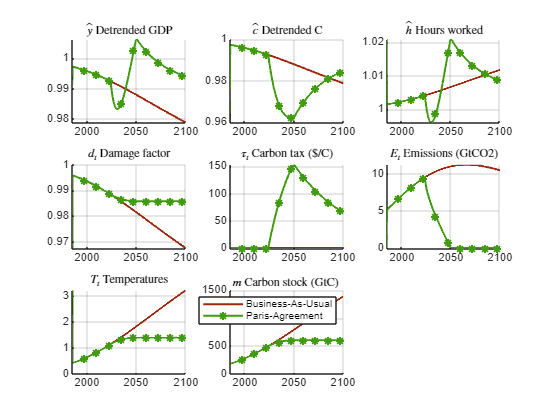

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),y_bau,'Color',[156, 40, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_bau,1))
	plotds(varnames(i1,:),y_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Business-As-Usual','Paris-Agreement')

## III. Delaying the implementation of the carbon tax to 2100

We now modify the exogenous path of the carbon tax shock `e_tau` to impose a more gradual and delayed implementation.

Instead of ramping up from the start of the simulation, the tax now increases linearly from zero to its full level between 2023Q4 and 2100Q4, and then remains constant.

We construct a new exogenous dataset `exo_init_ts2` with this delayed tax path and use it to recompute the deterministic transition under the same net-zero policy parameters. The resulting path, `y_nz02`, describes a transition where the effective carbon tax is postponed relative to the baseline net-zero scenario.

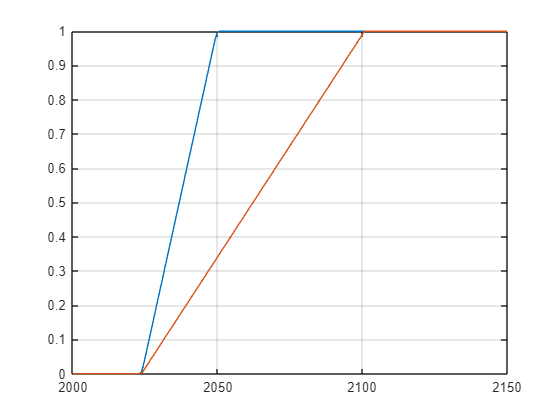

% making a copy
idtau     						 = strmatch('e_tau',M_.exo_names,'exact');
id_now    						 = find(exo_init_ts.dates==dates('2023Q3')+1);		% initial period of simulation
id_taxmax 						 = find(exo_init_ts.dates==dates('2100Q4'));		% when policy is fully implemented
exo_init2 						 = exo_init_ts.data;
exo_init2(id_now:id_taxmax,idtau) = linspace(0,1,(id_taxmax-id_now)+1);
exo_init2(id_taxmax:end,idtau)    = 1;
exo_init_ts2 					 = dseries(exo_init2,exo_init_ts.dates(1),exo_init_ts.name);

figure;
plotds('e_tau',exo_init_ts)
hold on;
plotds('e_tau',exo_init_ts2)
hold off;
xlim([2000 2150])
grid on;


% Step 1: Compute the deterministic path under the new policy
[y_nz02] = EP_deterministic_path(y_nz0, exo_init_ts2, oo_nz0, M_nz0, options_);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.655516,	 time = 0.098
Iter: 2,	 err. = 0.237348,	 time = 0.083
Iter: 3,	 err. = 0.000431338,	 time = 0.082
Iter: 4,	 err. = 1.67006e-10,	 time = 0.081

Total time of simulation: 0.444.
--------------------------------------------------------



We now compare the deterministic transition under two versions of the net-zero policy:

- **Paris-Agreement scenario** `y_nz0`, where the carbon tax ramps up immediately according to the baseline transition path.

- **Delayed-transition scenario** `y_nz02`, where the carbon tax is postponed and only reaches its full level by 2100.

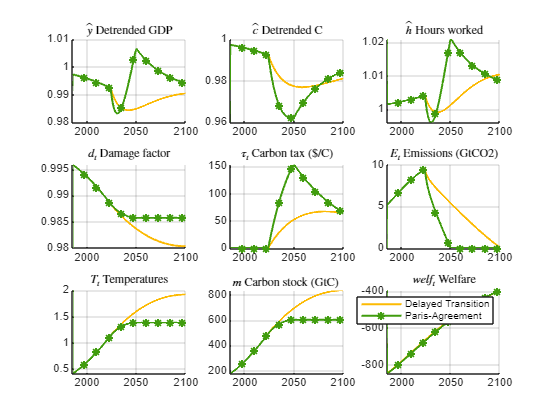

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M','welfare');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),y_nz02,'Color',[252, 186, 3]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_bau,1))
	plotds(varnames(i1,:),y_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Delayed Transition','Paris-Agreement')

## IV. Optimal carbon tax

We now compute the social cost of carbon (SCC) by optimizing the path of the carbon tax shock `e_tau` over a given horizon. The idea is to treat the tax path as a control variable and choose it to maximize welfare (or equivalently minimize the negative of welfare) along the transition.

We select welfare as the objective variable and the path of `e_tau` between 2025Q1 and 2100Q1 as the control. Using `fmincon`, we solve for the welfare-maximizing tax trajectory subject to bounds between 0 and 1, starting from the nominal BAU path. The resulting optimized tax sequence defines the implied SCC along the transition.

update_path_dates 	= dates('2025Q1'):dates('2100Q1');
scc_ts              = solve_op timal_policy('e_tau','welfare',update_path_dates,exo_init_ts,y_nz0,oo_nz0,M_nz0,options_);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         302    6.650056e+02     0.000e+00     1.000e+00     0.000e+00     1.412e-01  
    1         604    6.636096e+02     0.000e+00     1.000e+00     1.313e+00     1.007e-01  
    2         906    6.614184e+02     0.000e+00     1.000e+00     3.272e+00     4.178e-01  
    3        1208    6.609090e+02     0.000e+00     1.000e+00     1.619e+00     3.703e-01  
    4        1512    6.608706e+02     0.000e+00     4.900e-01     7.067e-01     1.090e-01  
    5        1814    6.604491e+02     0.000e+00     1.000e+00     1.199e+00     2.791e-01  
    6        2116    6.599659e+02     0.000e+00     1.000e+00     1.932e+00     3.705e-01  
    7        2418    6.599567e+02     0.000e+00     1.000e+00     1.216e+00     4.027e-01  
    8        2722    6.599560e+02     0.000e+00     4.900e-01     5.073e-01     1.

[det_nz0_1] 		= EP_deterministic_path(y_nz0,scc_ts,oo_nz0,M_nz0,options_);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.90683,	 time = 0.104
Iter: 2,	 err. = 0.596188,	 time = 0.127
Iter: 3,	 err. = 0.00206593,	 time = 0.104
Iter: 4,	 err. = 2.37626e-08,	 time = 0.107

Total time of simulation: 0.534.
--------------------------------------------------------



Then solve and plot

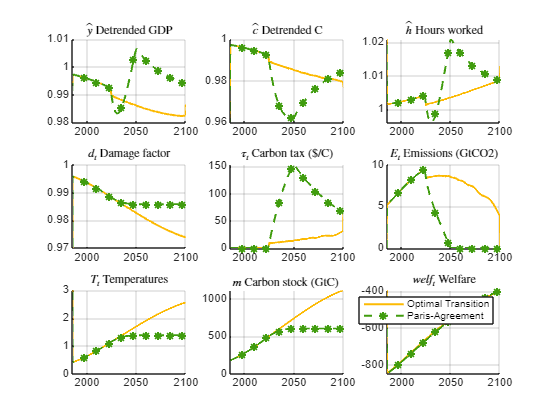

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M','welfare');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),det_nz0_1,'Color',[252, 186, 3]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(det_nz0_1,1))
	plotds(varnames(i1,:),y_nz0,'*--','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Optimal Transition','Paris-Agreement')